% read in a default audio file
[s, Fs] = audioread('guitartune.wav');

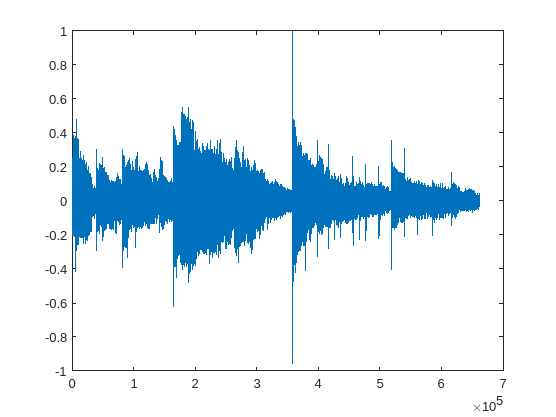

plot(s)

% uncomment to play guitar sound
% sound(s, Fs)

epochs = 10;
var = 2e-5; %sigma^2

% filter order (idk what number we want)
L = 40; 

mu = 0.002 %from pg. 9 (but should probably do eq 29b)

mu = 0.0020

% create noise
rand_noise = randn(size(s));
r = sqrt(var)*rand_noise; 

% use some window filter... chebyshev? idk what numbers we want
[b, a] = cheby2(5, 10, 0.5)

b =     0.3942    0.8173    1.2500    1.2500    0.8173    0.3942


a =     1.0000    0.9156    1.4118    0.9298    0.5112    0.1546


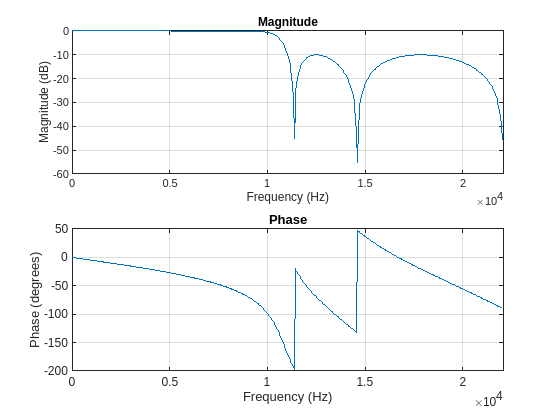

freqz(b, a, [], Fs)

% filter, put in transfer function and noise (with designated var)
r_filt = filter(b, a, r)

r_filt =     0.0016
    0.0010
   -0.0012
   -0.0032
   -0.0009
    0.0036
    0.0053
    0.0038
    0.0007
    0.0016


% signal plus noise
x = s + r_filt

x =     0.0016
    0.0010
   -0.0012
   -0.0032
   -0.0009
    0.0036
    0.0053
    0.0038
    0.0007
    0.0016


% uncomment for sound of signal plus noise
sound(x, Fs)

% do gradient descent here (two nested for loop) (n=1:epochs and k=1:L+P (maybe))
% w_n+1[k] = w_n[k] + mu[n]*e[n]*x[n] or w_n+1[k] = w_n[k] + 2*mu[n]*e[n]*x[n]
% y_k = w*r(k to end)
% e_k = x_k - y_k

P = length(r_filt);

e = zeros(size(r_filt));
w = zeros(1, L+1);
y = zeros(size(r_filt));

for n = 1:epochs
    
    for k = L+1:P
        y(k) = w * r(k:-1:k-L);
        e(k) = x(k) - y(k);
        w = w + 2*mu*e(k)*r(k:-1:k-L).';
    end

end

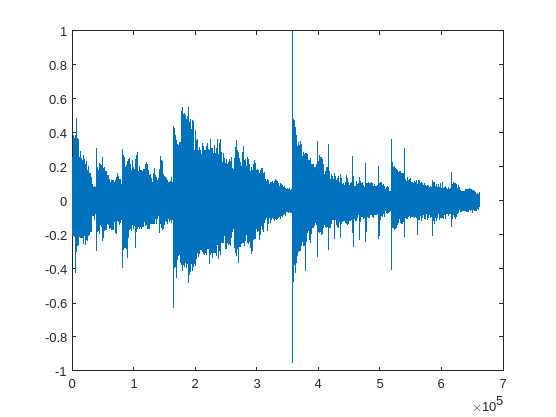

plot(e)

% sound(e, Fs)